# Dynamic Visualization Tutorial

Copyright © 2025, The MathWorks, Inc.

## Introduction

In this tutorial, we will explore using MATLAB Handle Graphics to enhance the output of simulations in Simscape Electrical. There are three main visualization components we will explore - time-series data, switches and rotating vectors. We will cover rotating vectors in tutorial number 02.

## Diode

Open the following model that contains a single diode and resistive load being fed by an AC voltage. Forward voltage on the diode is near zero in this case.

open_system('single_diode')
out = sim('single_diode');

View the source and load voltages in the Simulation Data Inspector (SDI). Note that the load does not receive negative voltage due to the diode blocking reverse voltage.

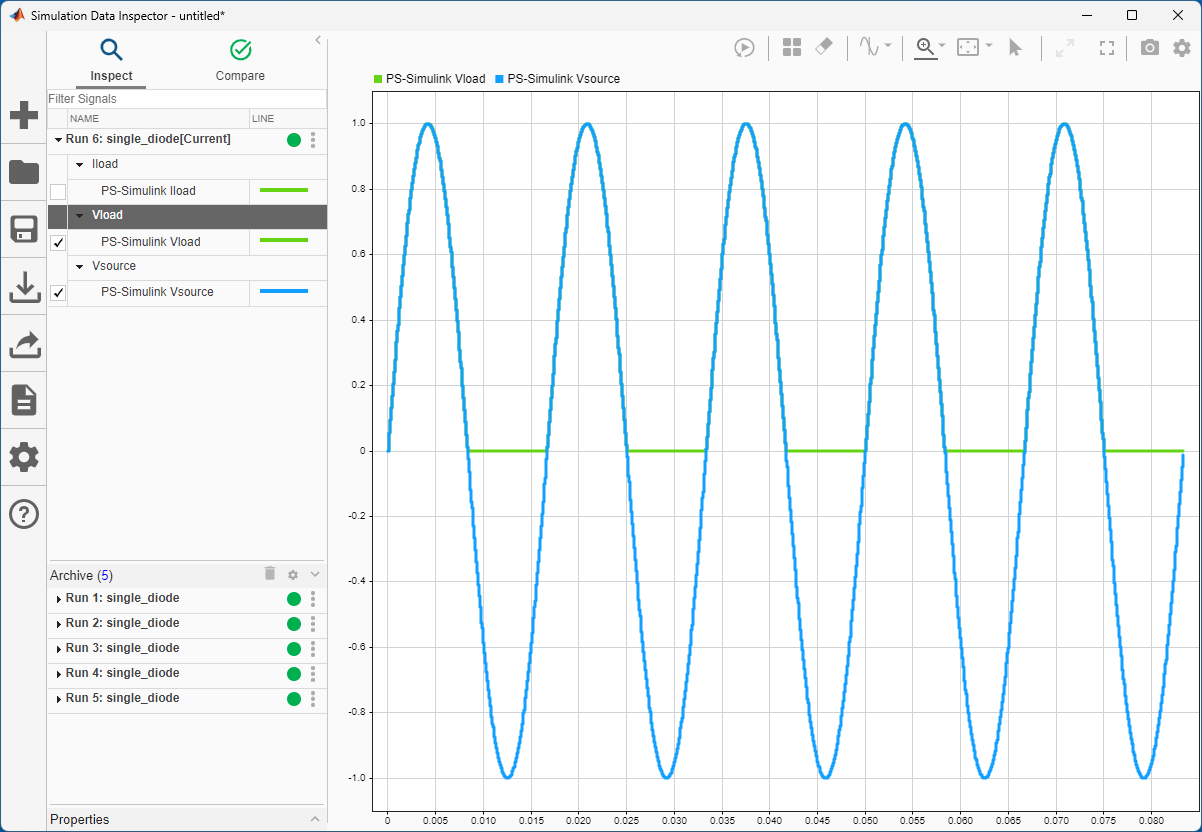

 We'll now use MATLAB Handle Graphics to build a visualization of a diode.

Start by creating a figure window, and include the figure handle. Then add axes using gca (get current axes), and include the handle to the axes.

close all % close existing figures

hf = figure(1)

hf =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [583 398 560 337.4462]
       Units: 'pixels'

  Show all properties


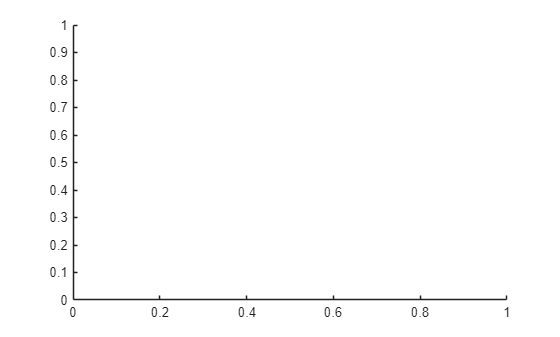

ha =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ha = gca

On the right you can see some of the properties of both hf and ha

The figure and the axes are objects and hf and ha allows us to access and modify the object properties. For example, to change the color of the figure to all white, we can use dot notation or the set command.

hf.Color = 'w';

or

set(hf,'Color','w')

OK. Let's start building a visualization of a diode. We will use the plot command and build up the diode from a series of lines.

Start with a vertical line

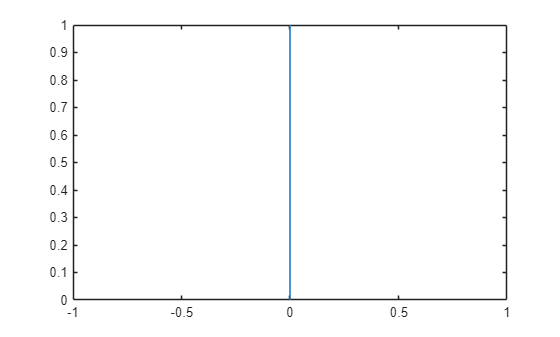

hp = plot([0 0],[0 1]);

Color it black

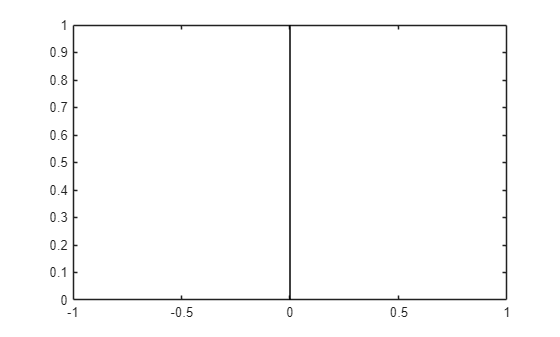

hp.Color = 'k';

Make it thicker

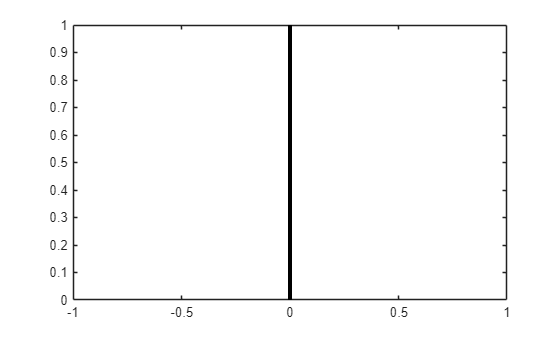

hp.LineWidth = 3;

Building each individual line with individual plot commands may not be the most efficient way to do things, so will use one plot command and create multiple lines within the single plot object. We'll color each line black as we go.

hp = plot([0 0],[0 1],'k',...
    [1 1],[0 1],'k',...
    [0 1],[1 0.5],'k',...
    [0 1],[0 0.5],'k',...
    [-1 0],[0.5 0.5],'k',...
    [1 2],[0.5 0.5],'k');

And expand the axes so we can see what we have more clearly

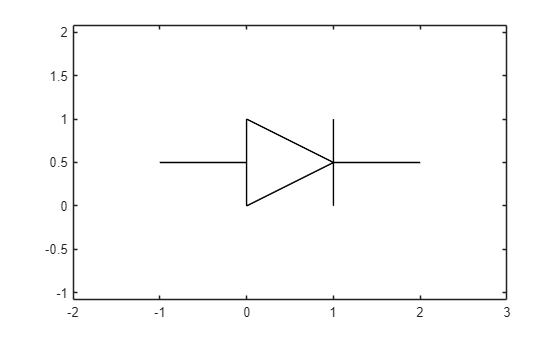

axis([-2 3 -1 2],'equal')

We'll make this image thicker, but we can't use dot notation directly on hp as it is made up of six separate lines. If you want to use dot notation you must access each separate line object. Here's the first two being made thicker.

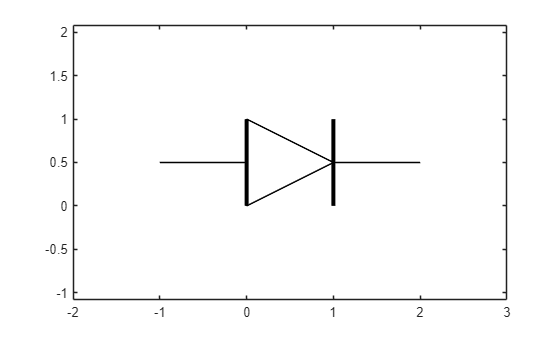

hp(1).LineWidth = 3;
hp(2).LineWidth = 3;

Dot notation is quite inefficient if you want to change all lines in an object the same way. To change each line together, use the set command.

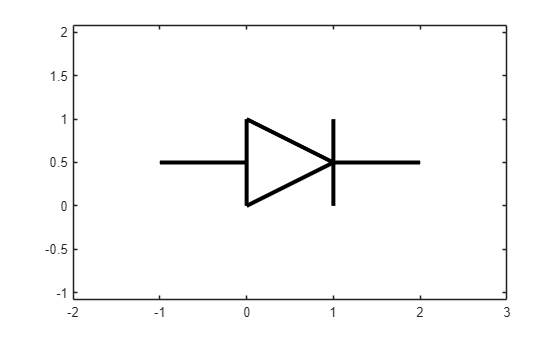

set(hp,'LineWidth',3)

Change the color to red

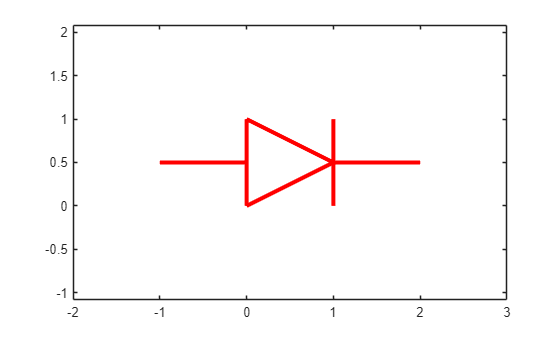

set(hp,'Color','r')

We'll set up a basic animation where we change the color of the diode from black to red every second for 10 seconds

for x = 1:10
   
    if rem(x,2) == 0
        set(hp,'Color','r')
    else
        set(hp,'Color','k')
    end
    
    pause(1)
    
end

Next we'll add time-series data of source and load voltage. We'll place source voltage to the left of the diode, and load voltage to the right.

First, set up the x-axis location of each time-series window, and decide how many time-steps you need in the x-axis. For example, we will set up the source voltage x-axis to be between x = -7 and x = -2, with 500 sample times.

xsource = linspace(-7,-2,500);

And set up the load voltage x-axis to be between x = 3 and x = 8, with 500 sample times

xload = linspace(3,8,500);

We have already run the simulation and so have access to the simulation data through the 'out' structure. We will create new variables that are easier to work with.

time    = squeeze(out.Vload.Time);
vload   = squeeze(out.Vload.Data);
vsource = squeeze(out.Vsource.Data);

Plot the source voltage, and use the 'hold on' command so that all objects will be rendered on the axes. Add color and linewidth definitions in the plot command (or use the set command - your choice)

hold on
hvs = plot(xsource,vsource(1:500),'Color','r','LineWidth',3);
axis([-8 9 -1.5 2.5],'equal')


Plot the load voltage

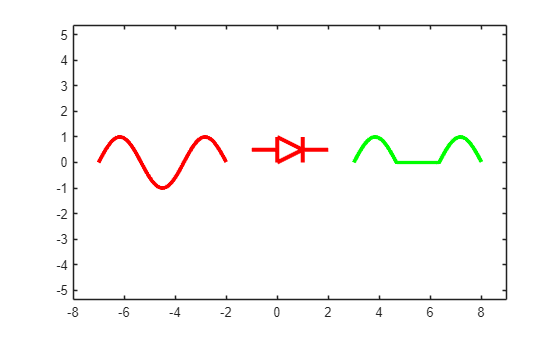

hvl = plot(xload,vload(1:500),'Color','g','LineWidth',3);

Now we want the time-series data to scroll as time progresses, and we want the diode to change color depending on whether it is conducting or not conducting.

We'll start with the scrolling time-series visualization. We set up a loop that will step through the simulation data at each time-step, and we include a pause command that gives us a reasonable dynamic (not too fast - not too slow). Note that we only update time-series y-axis data - there is no need to update the x-axis data.

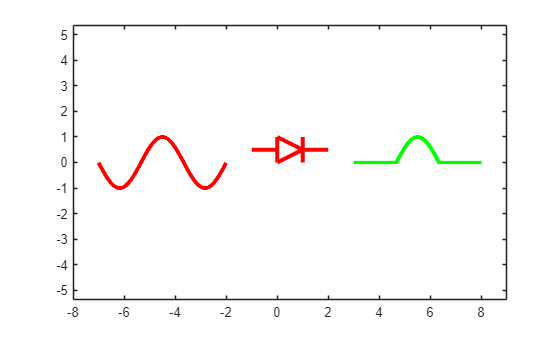


nt = numel(time); % number of time-steps

for x = 1:nt-500 % subtract the time-series window length

    set(hvs,'YData',vsource((1:500)+x)) % update y-axis data
    set(hvl,'YData',vload((1:500)+x)) % update y-axis data

    pause(0.01)

end

The final piece is to add the diode color change. The color change triggers off the source voltage magnitude. We'll also add an x-axis on each time-series so we can clearly see the zero crossing point. Note that if you are plotting an element that you'll not change, you don't need to expose the handle. We'll also set the axes to invisible.

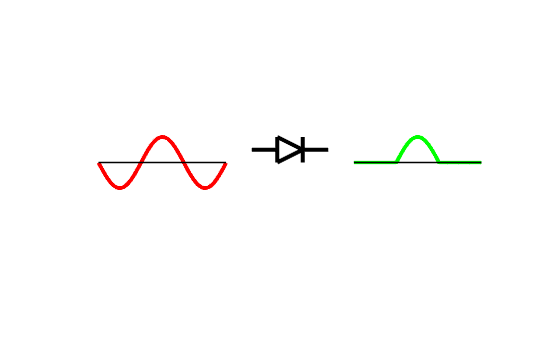


plot([-7 -2],[0 0],'k') % x-axis for source voltage
plot([3 8],[0 0],'k') % x-axis for load voltage

ha.Visible = 'off';

nt = numel(time); % number of time-steps

for x = 1:nt-500 % subtract the time-series window length

    set(hvs,'YData',vsource((1:500)+x)) % update y-axis data
    set(hvl,'YData',vload((1:500)+x)) % update y-axis data

    if vsource(500+x) > 0
        set(hp,'Color','g')
    else
        set(hp,'Color','k')
    end

    pause(0.01)
  
end

## Switch

Next we'll explore a switch visualization that not only changes color, but also changes its orientation depending on whether it's open or closed. Switch visualizations of this type are useful for visualization of controlled switches that turn on and off based on control signals. Open and run the simulation and create data variables to work with. 

open_system('single_switch')
out = sim('single_switch');

time2    = squeeze(out.Vload.Time);
vload2   = squeeze(out.Vload.Data);
vsource2 = squeeze(out.Vsource.Data);
switch2 = squeeze(out.switch1.Data);


Set up the figure and axes

close all
hf2 = figure(2);
hf2.Color = 'w';
ha2 = gca;

And build the simple switch

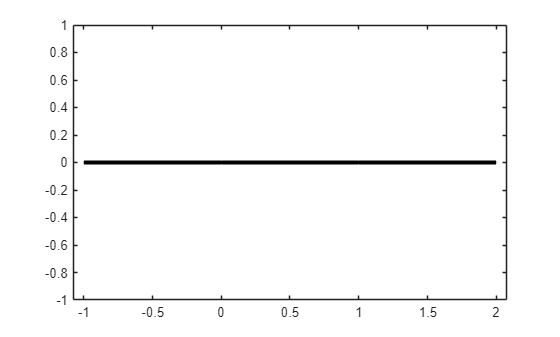

hsw = plot([0 1],[0 0],'k',...
    [-1 0],[0 0],'k',...
    [1 2],[0 0],'k');

set(hsw,'LineWidth',3)

axis([-1 2 -1 1],'equal')

The switch currently looks like a straight line. We'll make the switch thicker than its connecting lines. This is where accessing an individual line object is useful.

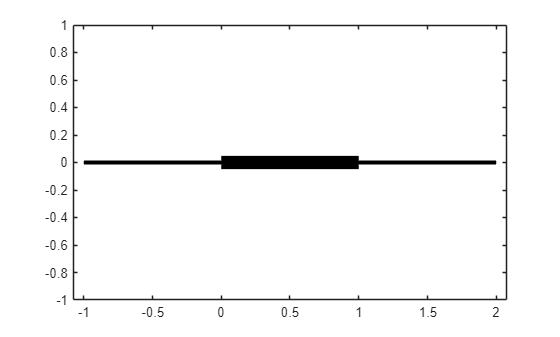

hsw(1).LineWidth = 10;

And we'll change the orientation to convey the switch is open - let's hinge it by 20 degrees.

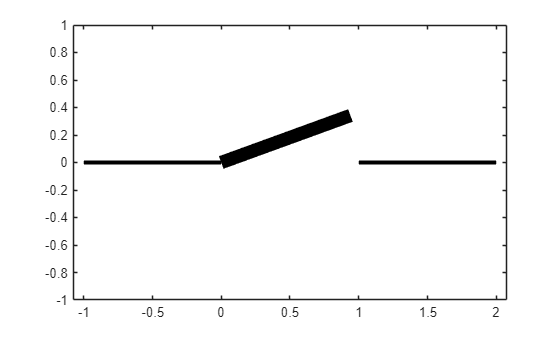

hsw(1).XData = [0 cos(20*pi/180)];
hsw(1).YData = [0 sin(20*pi/180)];

Now we'll build out the same visualization as before, but with our ideal switch in place of the diode.

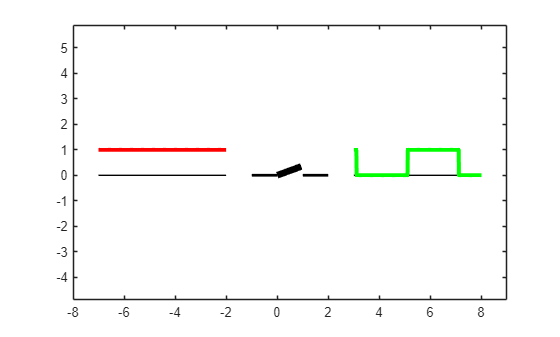

hold on

set(hsw,'LineWidth',2);
hsw(1).LineWidth = 5;

axis([-8 9 -1.5 2.5],'equal')

plot([-7 -2],[0 0],'k') % x-axis for source voltage
plot([3 8],[0 0],'k')   % x-axis for load voltage

xsource2 = linspace(-7,-2,500);
xload2   = linspace(3,8,500);

hvs2 = plot(xsource2,vsource2(1:500),'Color','r','LineWidth',3);
hvl2 = plot(xload2,vload2(1:500),'Color','g','LineWidth',3);

nt2 = numel(time2); % number of time-steps

for x2 = 1:nt2-500 % subtract the time-series window length

    set(hvs2,'YData',vsource2((1:500)+x2)) % update y-axis data
    set(hvl2,'YData',vload2((1:500)+x2))   % update y-axis data

    if switch2(500+x2) > 0
        set(hsw,'Color','g')
        set(hsw(1),'XData',[0 1],'YData',[0 0])
    else
        set(hsw,'Color','k')
        set(hsw(1),'XData',[0 cos(20*pi/180)],'YData',[0 sin(20*pi/180)])
    end

    pause(0.01)

end

END OF TUTORIAL 01